% Cargamos los datos
A = importdata("datos_calibración.txt");

CH1 = A(:,2);
CH2 = A(:,3);
CH3 = A(:,4);
CH4 = A(:,5);
CH5 = A(:,6);
CH6 = A(:,7);

% LS, LI, LCS, LCI
C_CH1 = [1895, 1115, 1500, 1510];
C_CH2 = [1858, 1124, 1486, 1496];
C_CH3 = [1855, 1150];
C_CH4 = [1900, 1150, 1515, 1535];
C_CH5 = [1900, 1100];
C_CH6 = [1920, 1120];

% Son simetricos?
m1 = abs(C_CH1(1)-C_CH1(4))

m1 = 385

abs(C_CH1(2)-C_CH1(3))

ans = 385

abs(C_CH1(1)-C_CH1(4)) == abs(C_CH1(2)-C_CH1(3))

ans = logical
   1


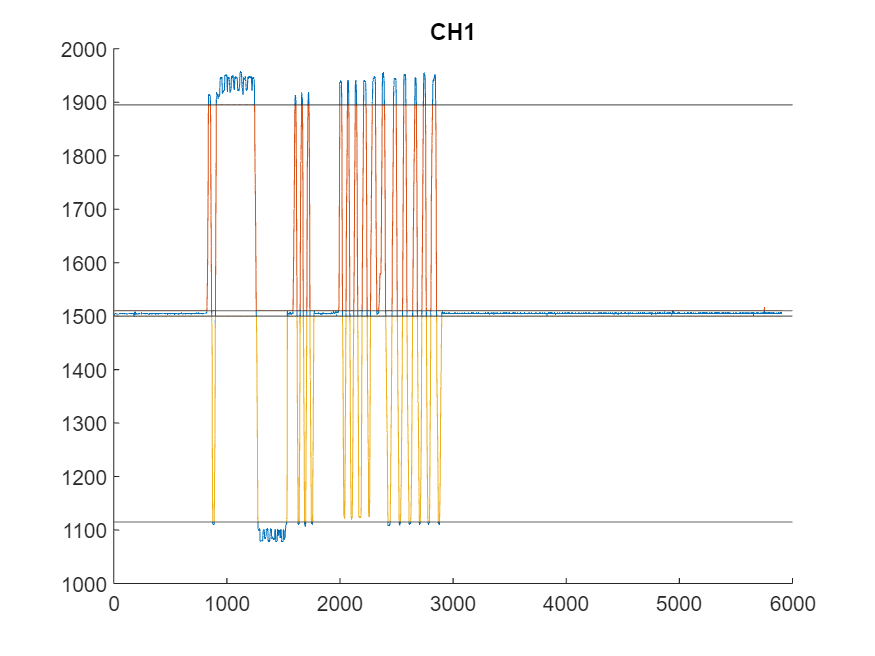


sat_CH1 = CH1;
sat_CH1 = min(sat_CH1, C_CH1(1));
sat_CH1 = max(sat_CH1, C_CH1(4));

sat2_CH1 = CH1;
sat2_CH1 = min(sat2_CH1, C_CH1(3));
sat2_CH1 = max(sat2_CH1, C_CH1(2));

figure; hold on;
plot(CH1)
plot(sat_CH1)
plot(sat2_CH1)
yline(C_CH1)
title("CH1")

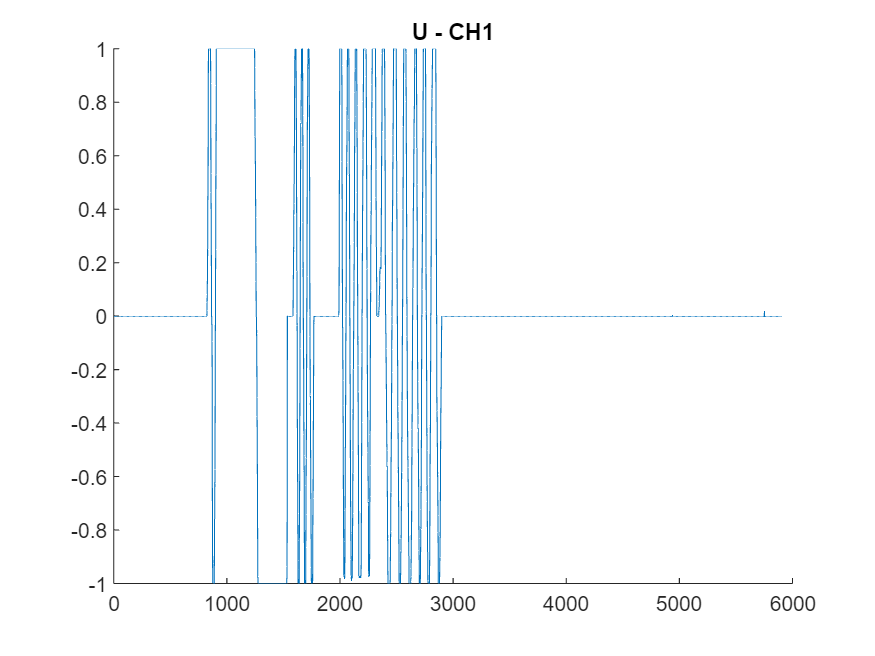


u1_CH1 = (1/m1)*(sat_CH1 - C_CH1(4));
u2_CH1 = (1/m1)*(sat2_CH1 - C_CH1(3));

figure; hold on;
% plot(u1_CH1)
% plot(u2_CH1)
plot(u1_CH1+u2_CH1)
title("U - CH1")


% Son simetricos?
m2 = abs(C_CH2(1)-C_CH2(4))

m2 = 362

abs(C_CH2(2)-C_CH2(3))

ans = 362

abs(C_CH2(1)-C_CH2(4)) == abs(C_CH2(2)-C_CH2(3))

ans = logical
   1


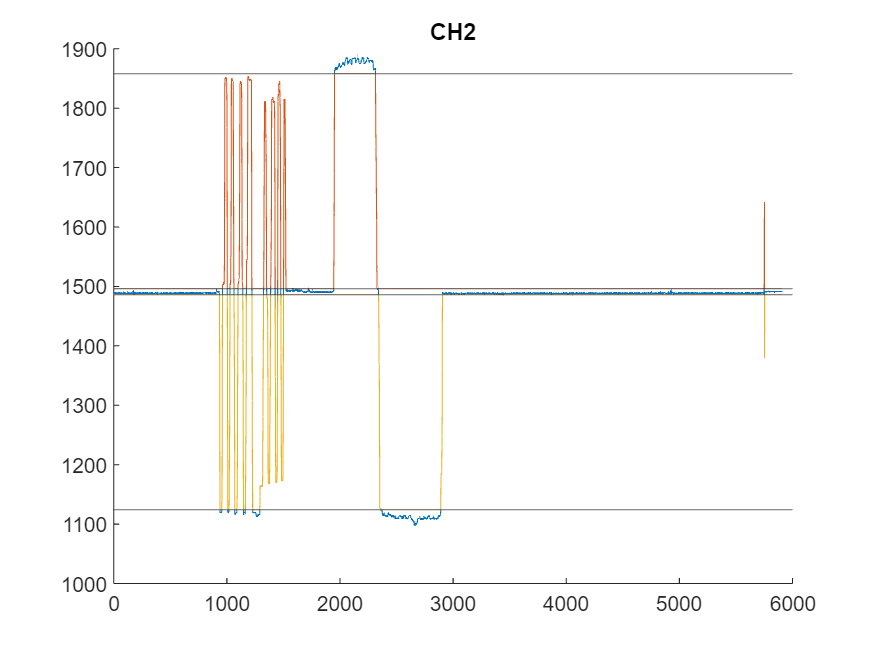


sat_CH2 = CH2;
sat_CH2 = min(sat_CH2, C_CH2(1));
sat_CH2 = max(sat_CH2, C_CH2(4));

sat2_CH2 = CH2;
sat2_CH2 = min(sat2_CH2, C_CH2(3));
sat2_CH2 = max(sat2_CH2, C_CH2(2));

figure; hold on;
plot(CH2)
plot(sat_CH2)
plot(sat2_CH2)
yline(C_CH2)
title("CH2")

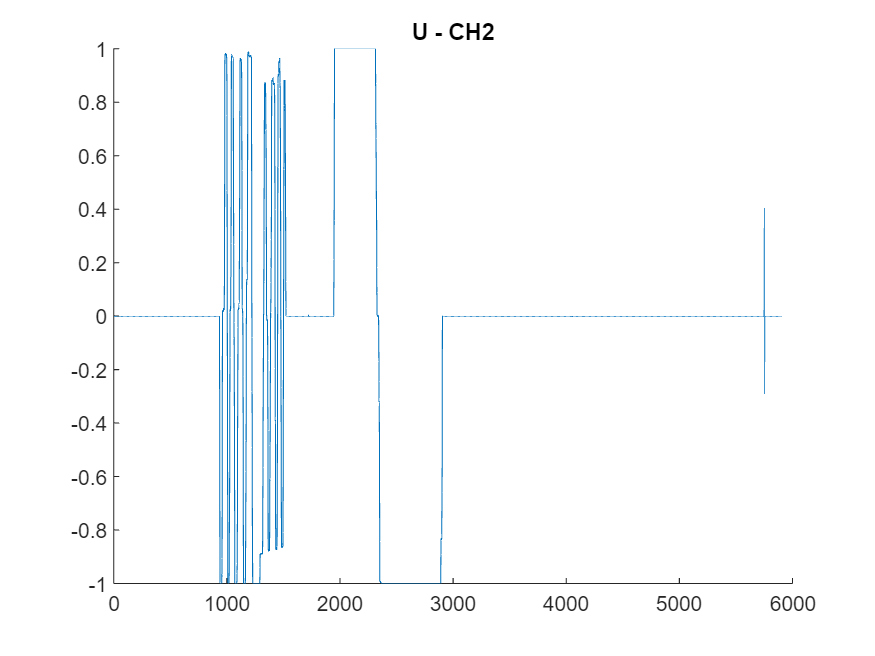


u1_CH2 = (1/m2)*(sat_CH2 - C_CH2(4));
u2_CH2 = (1/m2)*(sat2_CH2 - C_CH2(3));

figure; hold on;
% plot(u1_CH2)
% plot(u2_CH2)
plot(u1_CH2+u2_CH2)
title("U - CH2")

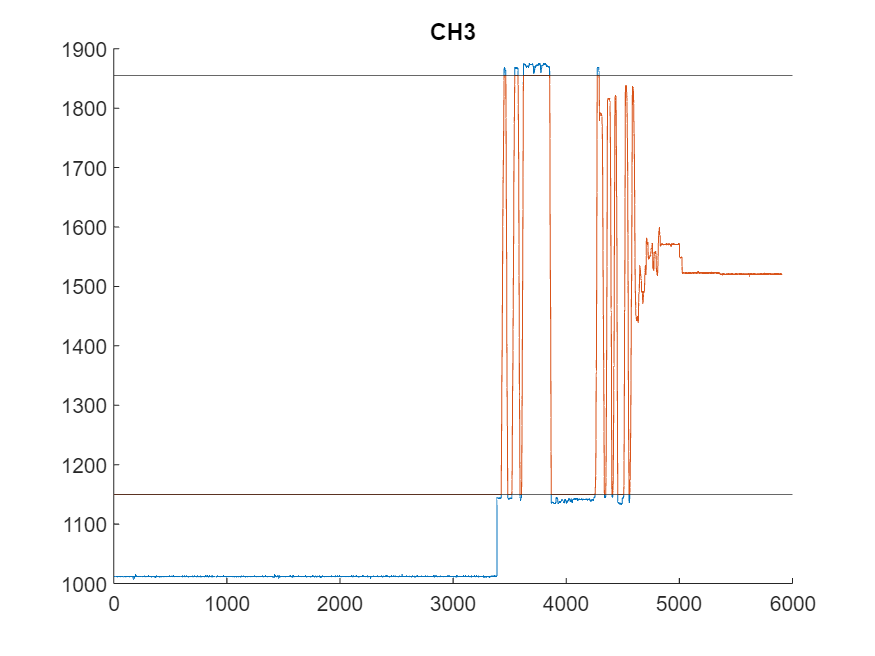



m3 = abs(C_CH3(1)-C_CH3(2));

sat_CH3 = CH3;
sat_CH3 = min(sat_CH3, C_CH3(1));
sat_CH3 = max(sat_CH3, C_CH3(2));

figure; hold on;
plot(CH3)
plot(sat_CH3)
yline(C_CH3)
title("CH3")

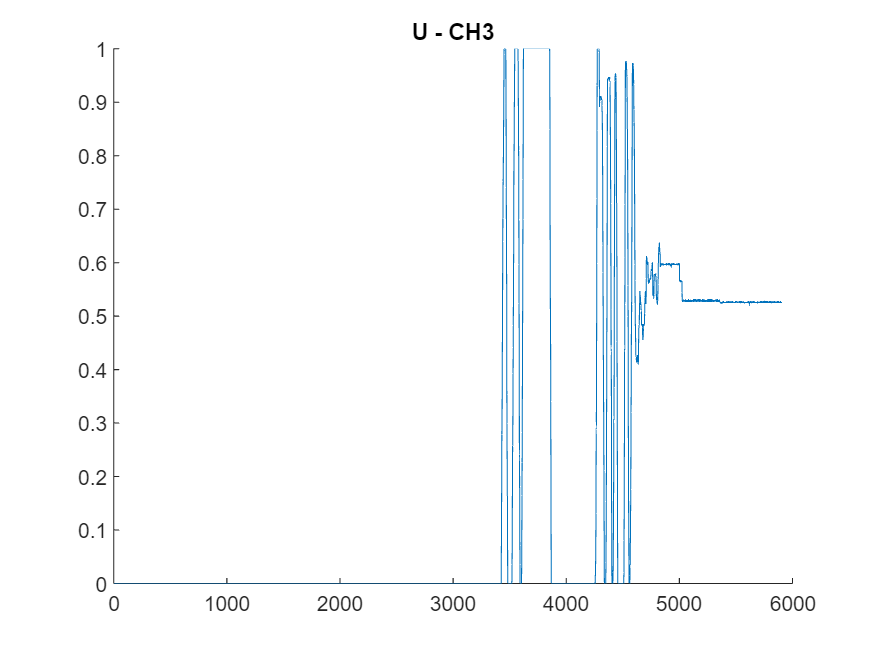


u_CH3 = (1/m3)*(sat_CH3 - C_CH3(2));

figure; hold on;
plot(u_CH3)
title("U - CH3")


% Son simetricos?
m4 = abs(C_CH4(1)-C_CH4(4))

m4 = 365

abs(C_CH4(2)-C_CH4(3))

ans = 365

abs(C_CH4(1)-C_CH4(4)) == abs(C_CH4(2)-C_CH4(3))

ans = logical
   1


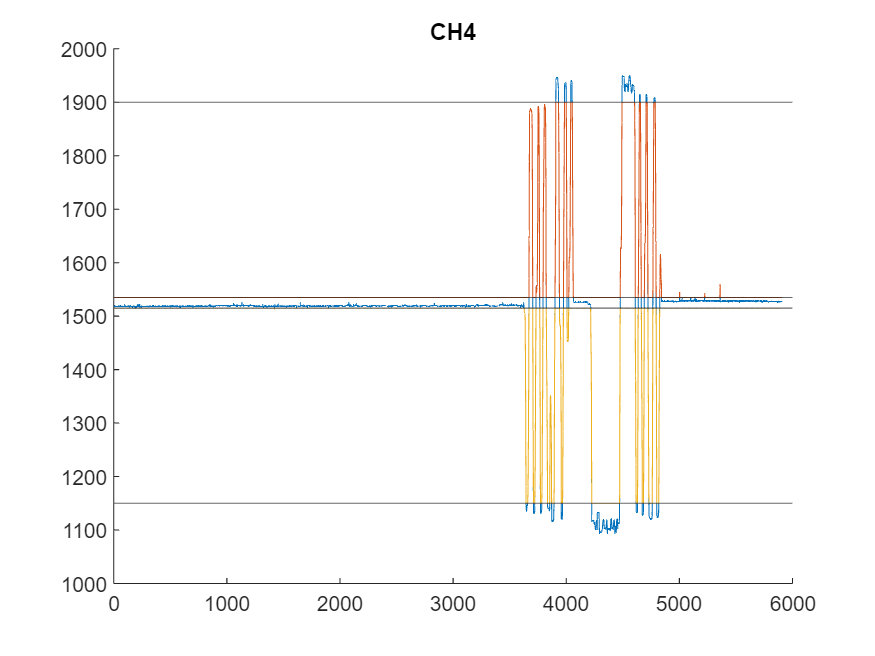


sat_CH4 = CH4;
sat_CH4 = min(sat_CH4, C_CH4(1));
sat_CH4 = max(sat_CH4, C_CH4(4));

sat2_CH4 = CH4;
sat2_CH4 = min(sat2_CH4, C_CH4(3));
sat2_CH4 = max(sat2_CH4, C_CH4(2));

figure; hold on;
plot(CH4)
plot(sat_CH4)
plot(sat2_CH4)
yline(C_CH4)
title("CH4")

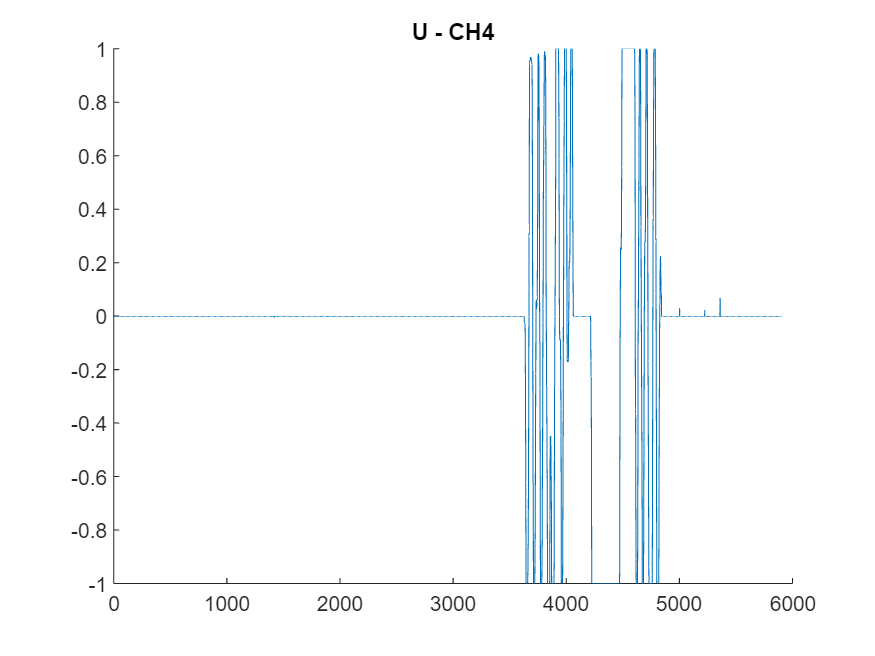


u1_CH4 = (1/m4)*(sat_CH4 - C_CH4(4));
u2_CH4 = (1/m4)*(sat2_CH4 - C_CH4(3));

figure; hold on;
% plot(u1_CH4)
% plot(u2_CH4)
plot(u1_CH4+u2_CH4)
title("U - CH4")

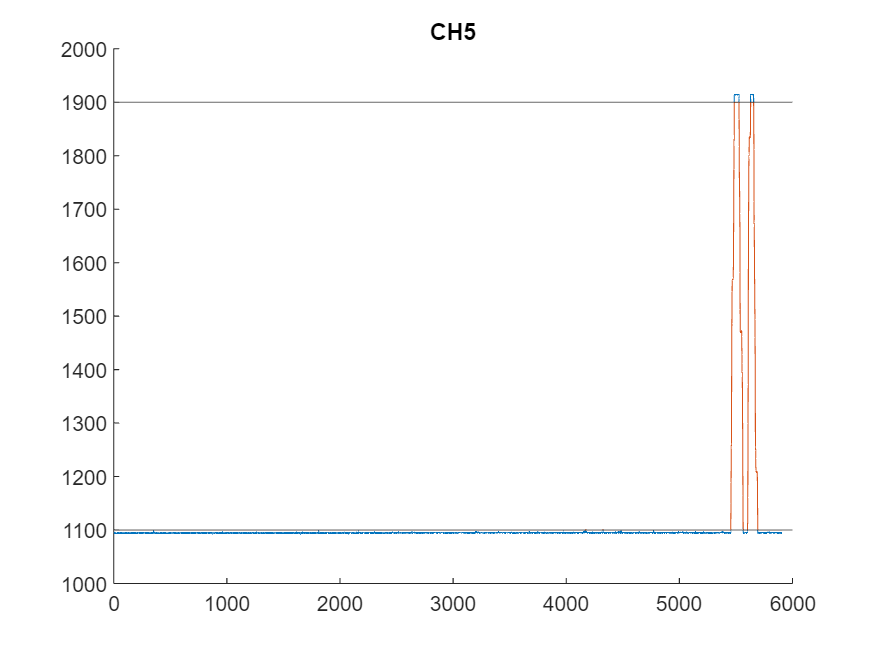



m5 = abs(C_CH5(1)-C_CH5(2));

sat_CH5 = CH5;
sat_CH5 = min(sat_CH5, C_CH5(1));
sat_CH5 = max(sat_CH5, C_CH5(2));

figure; hold on;
plot(CH5)
plot(sat_CH5)
yline(C_CH5)
title("CH5")

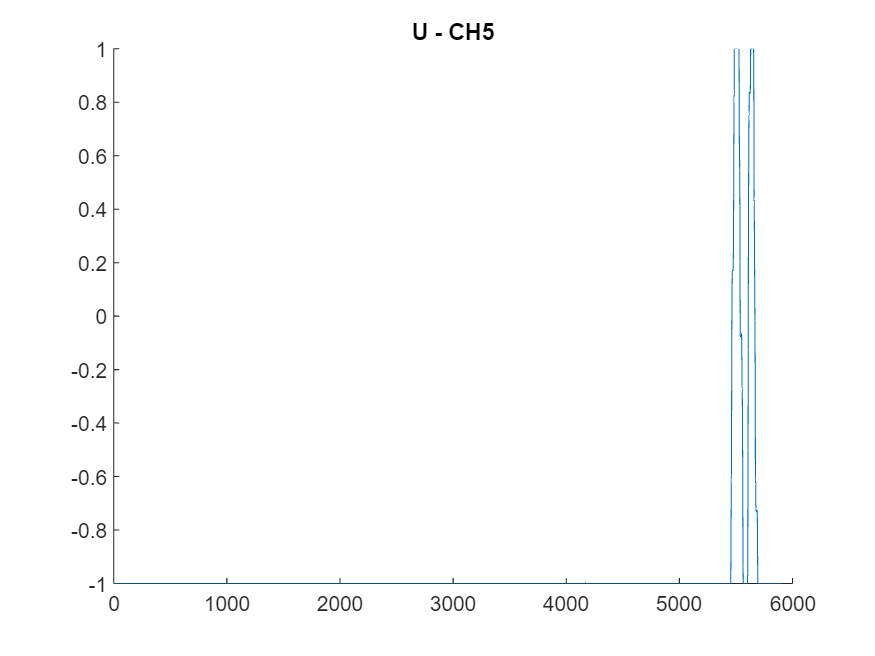


u_CH5 = (1/(m5/2))*(sat_CH5 - mean(C_CH5));

figure; hold on;
plot(u_CH5)
title("U - CH5")

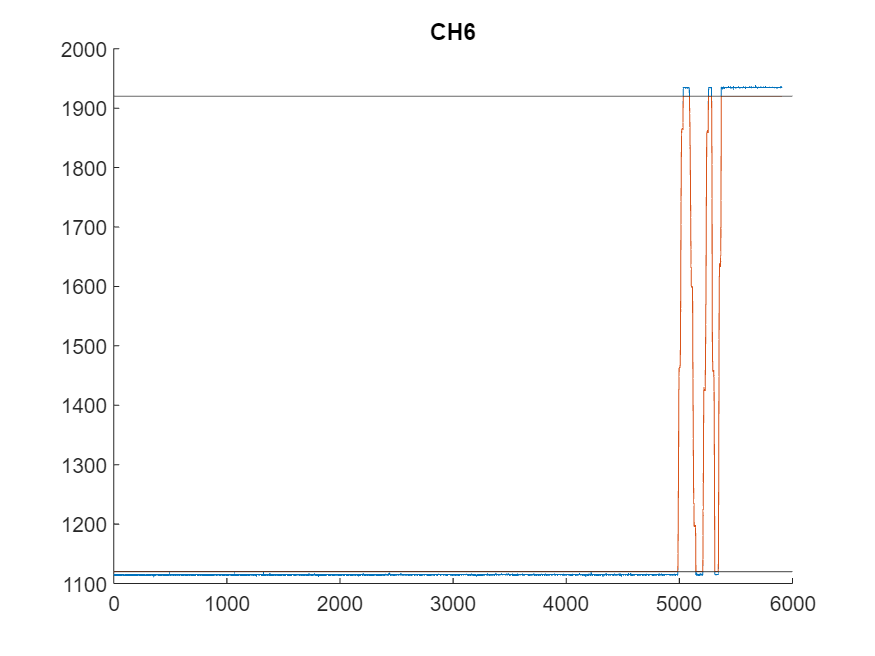



m6 = abs(C_CH6(1)-C_CH6(2));

sat_CH6 = CH6;
sat_CH6 = min(sat_CH6, C_CH6(1));
sat_CH6 = max(sat_CH6, C_CH6(2));

figure; hold on;
plot(CH6)
plot(sat_CH6)
yline(C_CH6)
title("CH6")

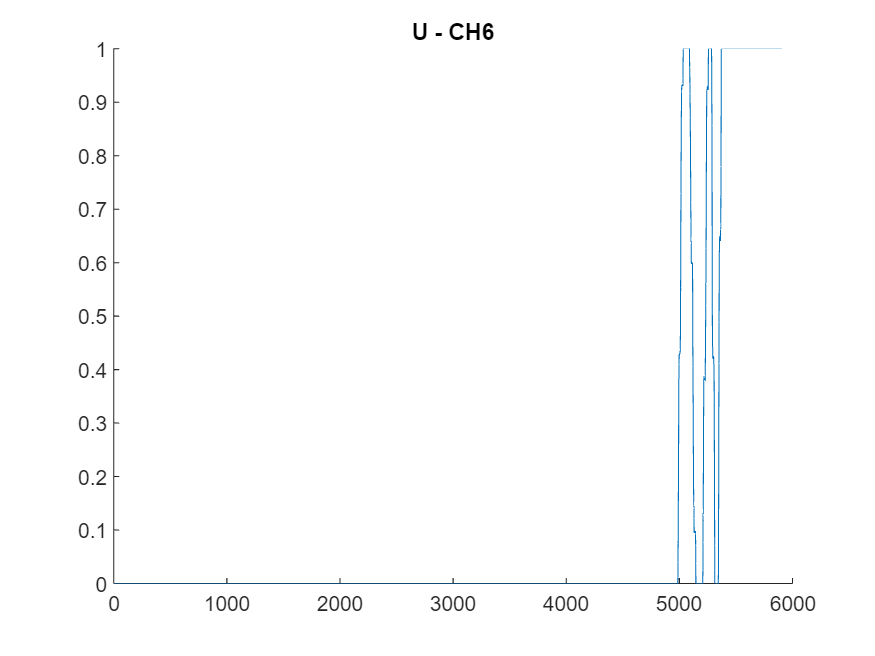


u_CH6 = (1/m6)*(sat_CH6 - C_CH6(2));

figure; hold on;
plot(u_CH6)
title("U - CH6")